LoadData();

## Calculate the R2 Value for each combination of signals

warning('off','all')
correlatedSignalMatrix = cell(numOfSignals, numOfSignals);
correlatedSignalMatrix2 = cell(numOfSignals, numOfSignals);
for i = 1:numOfSignals
    for j = i:numOfSignals
        if i ~= j
            str = "";
            for k = 1:numOfFeatures
                sig1 = FeaturesAll.(signalName(i) + featureNames(k));
                sig2 = FeaturesAll.(signalName(j) + featureNames(k));
    
                mdl = fitlm(sig1, sig2);
                R2 = mdl.Rsquared.Ordinary;

                %if R2 > 0.9 && R2 < 1
                if R2 > 0.3 && R2 < 0.9
                    str = str + sprintf('%i %s %3g \n', k, featureNames(k), round(R2, 3));  
                    correlatedSignalMatrix{i, j} = [correlatedSignalMatrix{i, j} k];
                end
                correlatedSignalMatrix2{i, j} = [correlatedSignalMatrix2{i, j} R2];
            end
            if (str ~= "")
                disp( sensorNames(i) + " " + sensorNames(j) );
                disp(str)
            end
        end
    end
end

21:07 Angle over Rolls (degrees) 21:10 Position over Rolls (mm)


5 Mean 0.742 
6 PeakValue 0.743 
7 RMS 0.742 



21:07 Angle over Rolls (degrees) 21:12 Actual moment over Rolls (Nm)


6 PeakValue 0.309 



21:07 Angle over Rolls (degrees) 21:17 Angle under roll (degrees)


6 PeakValue 0.678 
7 RMS 0.719 



21:07 Angle over Rolls (degrees) 21:20 Actual moment under Rolls (Nm)


6 PeakValue 0.302 



21:07 Angle over Rolls (degrees) 21:28 Vibration measurements (mm per s)


1 ClearanceFactor 0.332 
2 CrestFactor 0.312 
3 ImpulseFactor 0.324 
12 Std 0.368 



21:07 Angle over Rolls (degrees) 21:31 Width position (mm)


5 Mean 0.456 
6 PeakValue 0.455 
7 RMS 0.456 



21:07 Angle over Rolls (degrees) 31:32 Height position (?)


5 Mean 0.712 
6 PeakValue 0.71 
7 RMS 0.712 



21:10 Position over Rolls (mm) 21:17 Angle under roll (degrees)


6 PeakValue 0.585 
7 RMS 0.616 



21:10 Position over Rolls (mm) 21:31 Width position (mm)


5 Mean 0.814 
6 PeakValue 0.816 
7 RMS 0.814 



21:12 Actual moment over Rolls (Nm) 21:17 Angle under roll (degrees)


6 PeakValue 0.377 
7 RMS 0.371 



21:12 Actual moment over Rolls (Nm) 21:20 Actual moment under Rolls (Nm)


4 Kurtosis 0.878 
8 SNR 0.875 
9 SINAD 0.879 



21:17 Angle under roll (degrees) 21:20 Actual moment under Rolls (Nm)


6 PeakValue 0.367 
7 RMS 0.36 



21:17 Angle under roll (degrees) 21:31 Width position (mm)


7 RMS 0.326 



21:17 Angle under roll (degrees) 31:32 Height position (?)


6 PeakValue 0.552 
7 RMS 0.585 



21:28 Vibration measurements (mm per s) 21:36 Actual force (KN)


5 Mean 0.304 



21:31 Width position (mm) 31:32 Height position (?)


5 Mean 0.825 
6 PeakValue 0.824 
7 RMS 0.825 



21:31 Width position (mm) 21:34 Error position for the width (?)


11 Skewness 0.423 



31:32 Height position (?) 21:33 Error position for height (?)


4 Kurtosis 0.419 
8 SNR 0.547 
9 SINAD 0.543 
12 Std 0.892 



31:32 Height position (?) 21:35 Set point force (KN)


1 ClearanceFactor 0.331 



21:33 Error position for height (?) 21:34 Error position for the width (?)


5 Mean 0.304 
7 RMS 0.304 
12 Std 0.326 



21:35 Set point force (KN) 21:36 Actual force (KN)


6 PeakValue 0.763 



correlatedSignalMatrix

correlatedSignalMatrix = 12×12 cell array
    {0×0 double}    {[   5 6 7]}    {[       6]}    {[     6 7]}    {[       6]}    {[1 2 3 12]}    {[   5 6 7]}    {[   5 6 7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {[     6 7]}    {0×0 double}    {0×0 double}    {[   5 6 7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {[     6 7]}    {[   4 8 9]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {[     6 7]}    {0×0 double}    {[       7]}    {[     6 7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

correlatedSignalMatrix2

correlatedSignalMatrix2 = 12×12 cell array
    {0×0 double}    {[0.0045 0.0045 0.0045 6.6166e-06 0.7420 0.7431 0.7420 NaN NaN 4.1326e-04 0.0022 0.0012 NaN]}    {[0.0044 0.0024 0.0036 2.3821e-05 0.2918 0.3093 0.2913 0.0027 8.3980e-04 0.0103 4.2784e-04 0.0188 NaN]}    {[0.1156 0.1171 0.1161 3.5307e-04 0.1657 0.6776 0.7185 NaN NaN 0.0069 0.0054 0.0639 NaN]}    {[0.0056 0.0022 0.0041 1.1533e-04 0.2865 0.3016 0.2860 0.0048 0.0014 0.0230 8.9171e-05 0.0368 NaN]}    {[  0.3317 0.3117 0.3239 0.0036 0.0120 0.0253 0.0127 0.0029 3.7360e-04 0.1418 0.0057 0.3683 NaN]}    {[           0.0207 0.0207 0.0207 6.6934e-05 0.4556 0.4549 0.4556 0.0115 0.0115 0.0096 0.0120 0.0019 NaN]}    {[      0.0017 0.0017 0.0017 0.0020 0.7122 0.7104 0.7122 0.0051 0.0056 9.0530e-04 2.5036e-05 0.0065 NaN]}    {[    0.0495 0.0511 0.0498 0.0031 0.0296 0.0102 0.0140 8.9118e-04 0.0012 0.0185 0.0245 0.0191 NaN]}    {[                   0.0593 0.0850 0.0744 1.1551e-05 0.0010 0.0036 0.0010 0.0113 0.0111 0.0114 0.0015 0.0071 NaN]}

## Plot signals that have R2 above threshold

Signal 1:Signal 3 - Features: 1

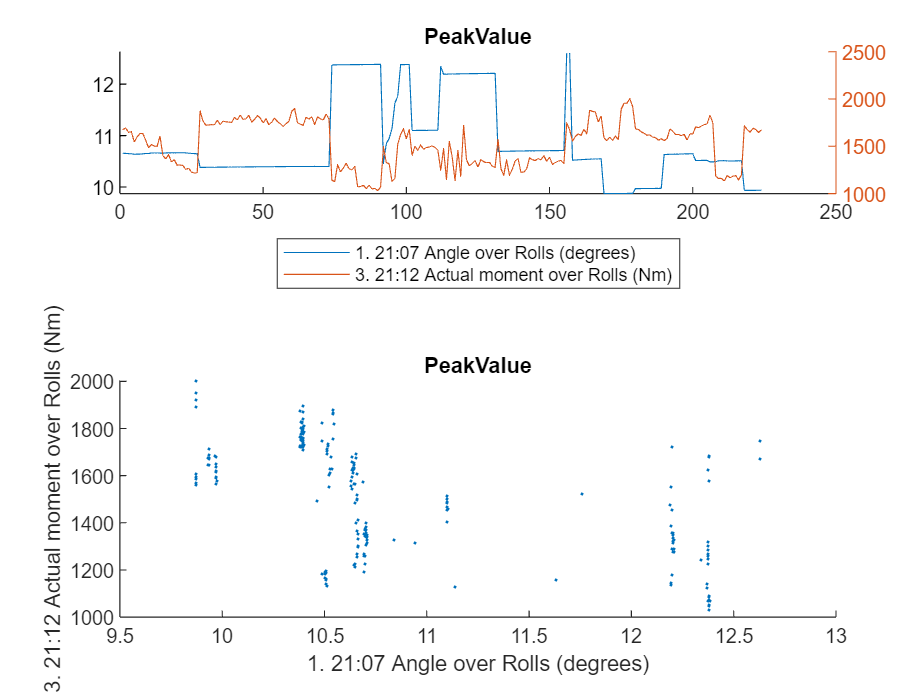

Signal 1:Signal 5 - Features: 1

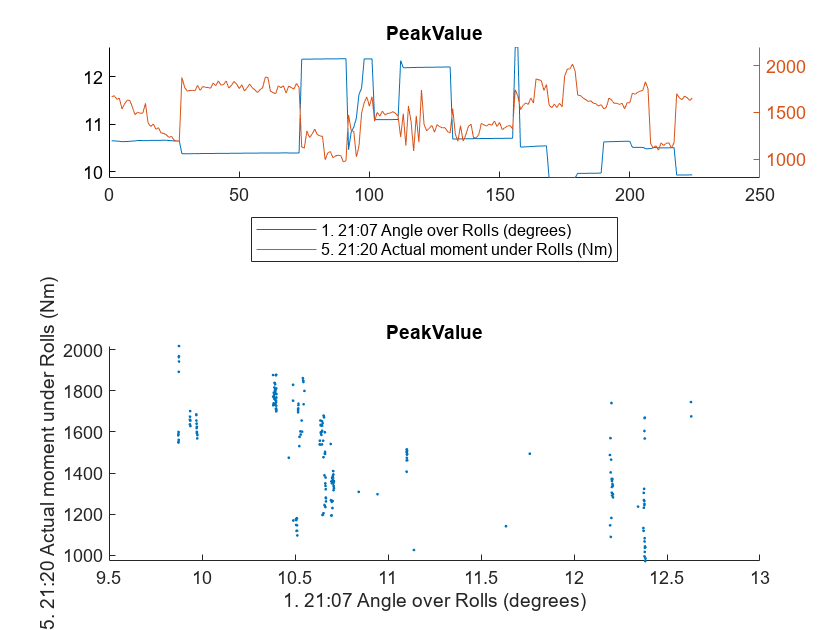

Signal 1:Signal 6 - Features: 4

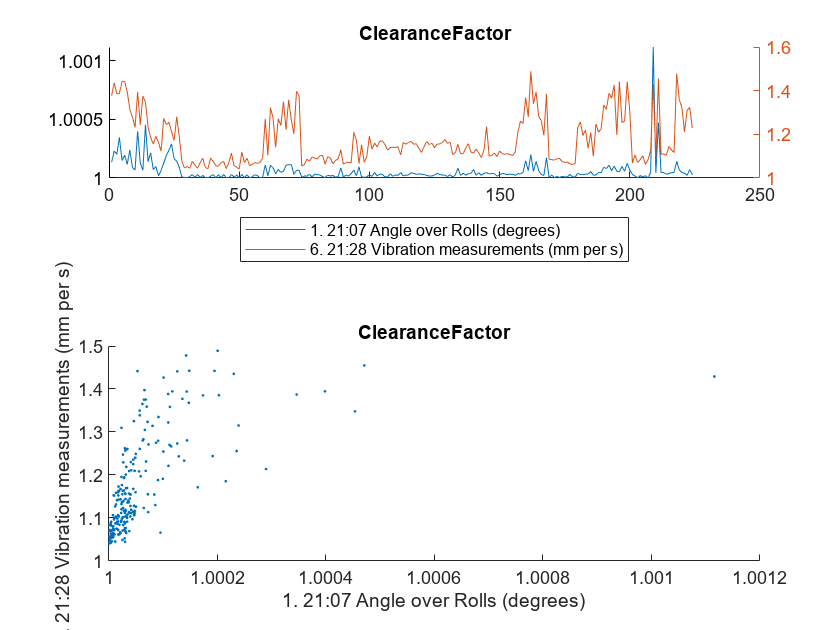

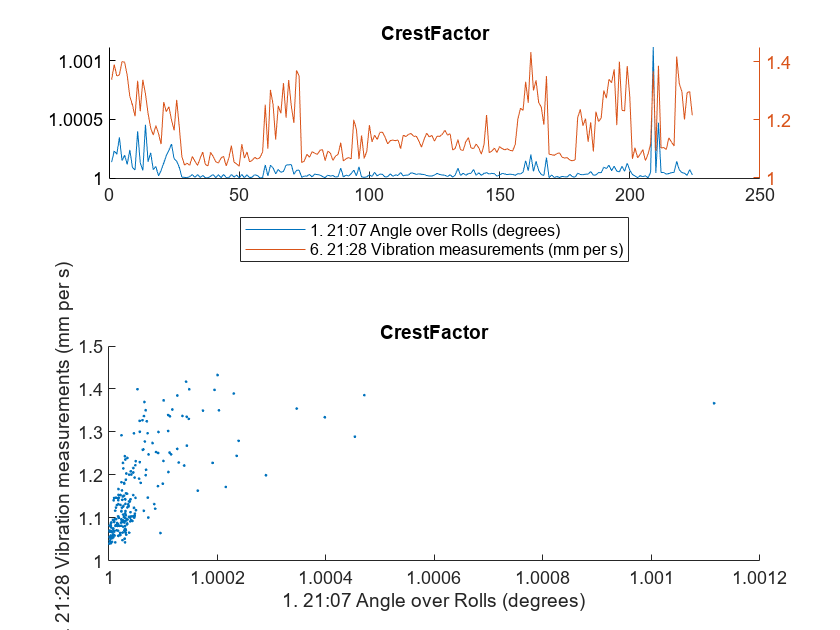

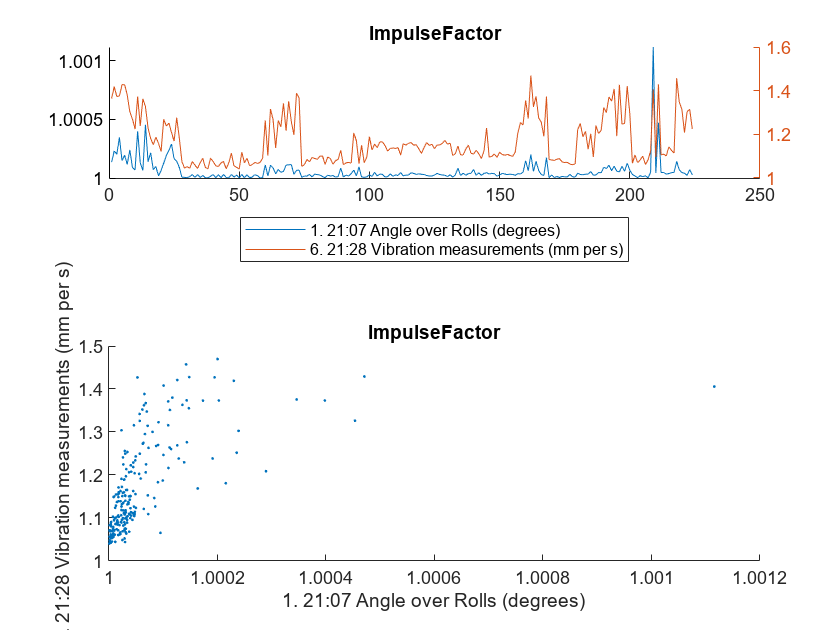

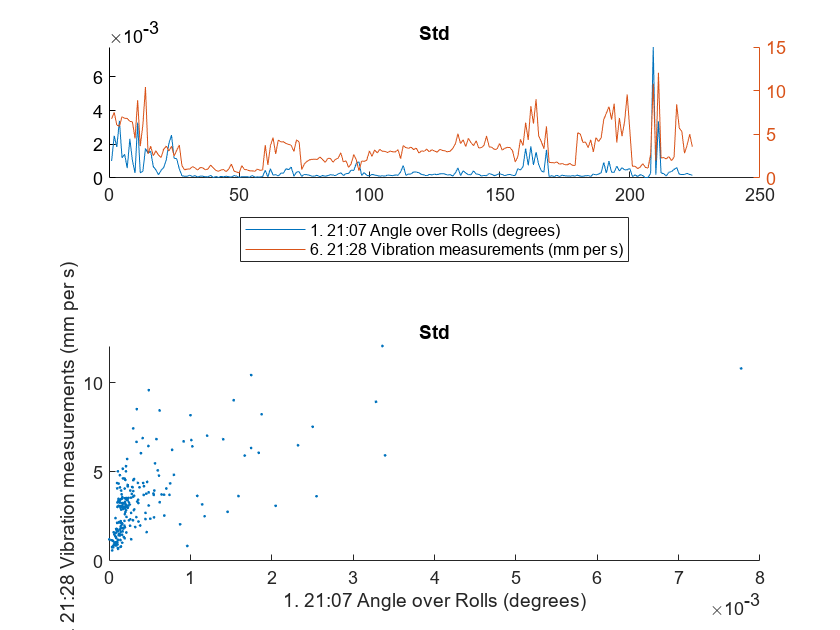

Signal 1:Signal 7 - Features: 3

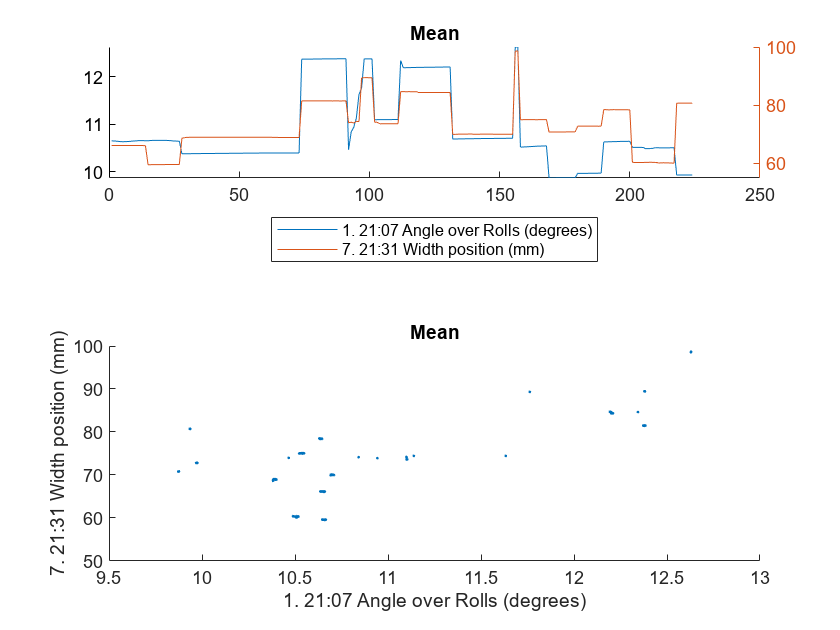

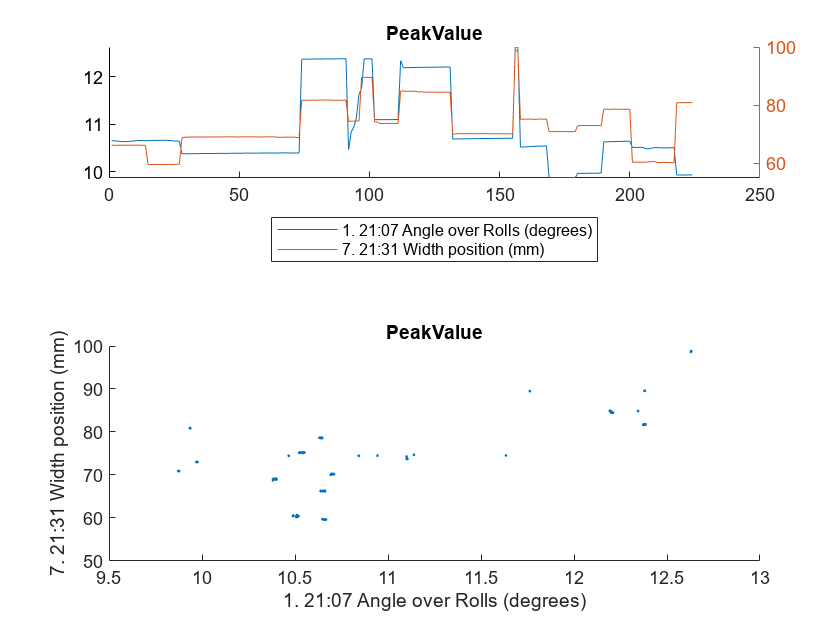

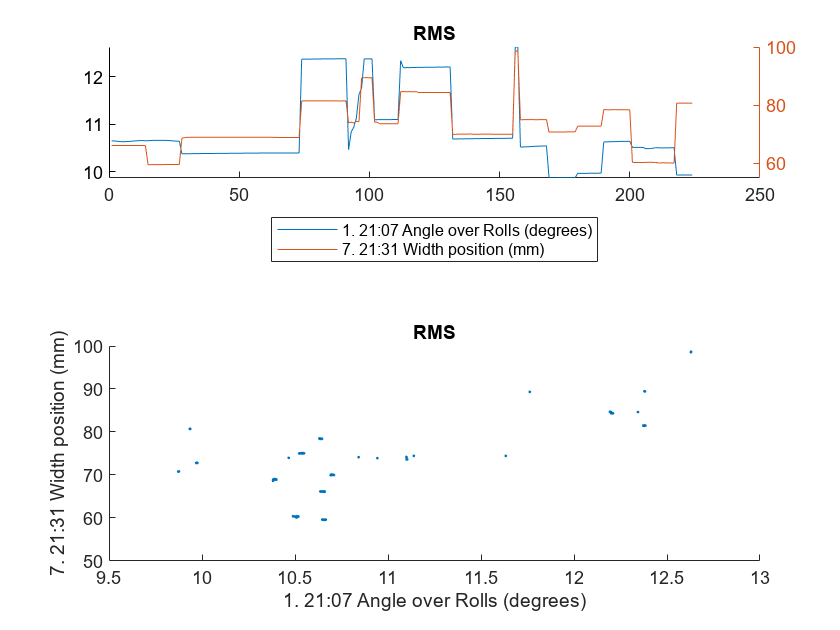

Signal 3:Signal 4 - Features: 2

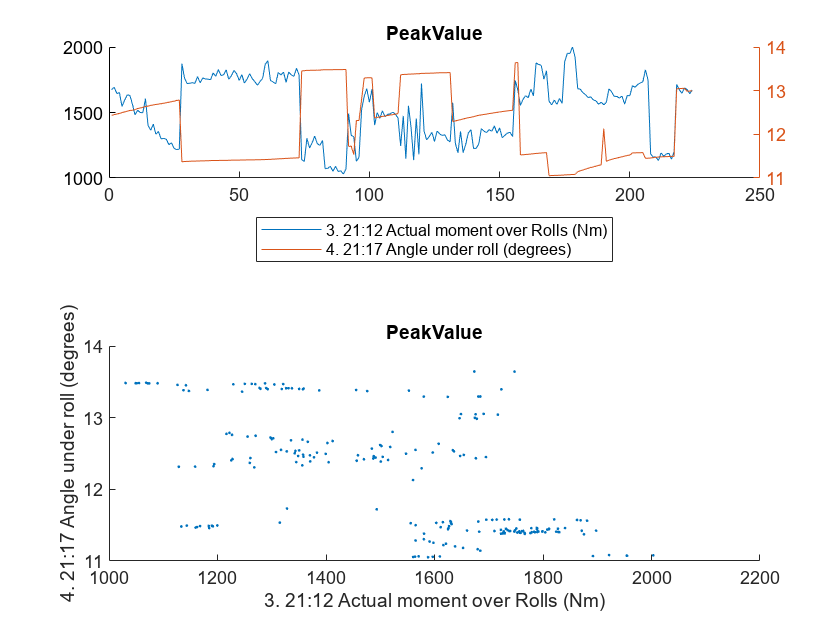

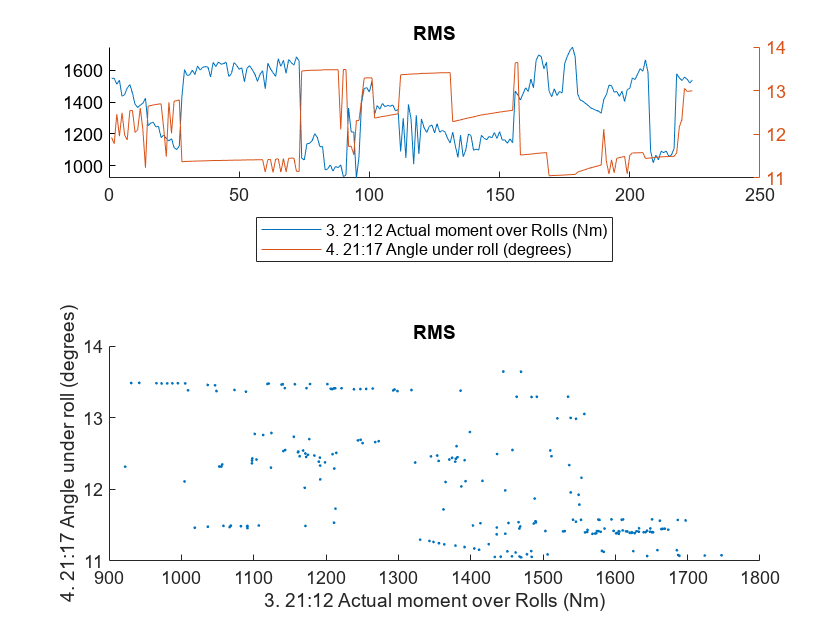

Signal 4:Signal 5 - Features: 2

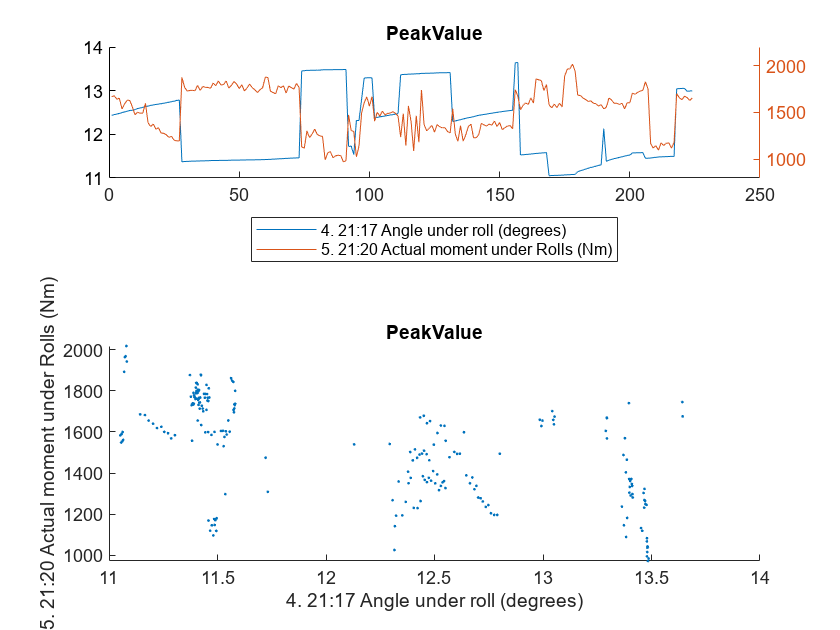

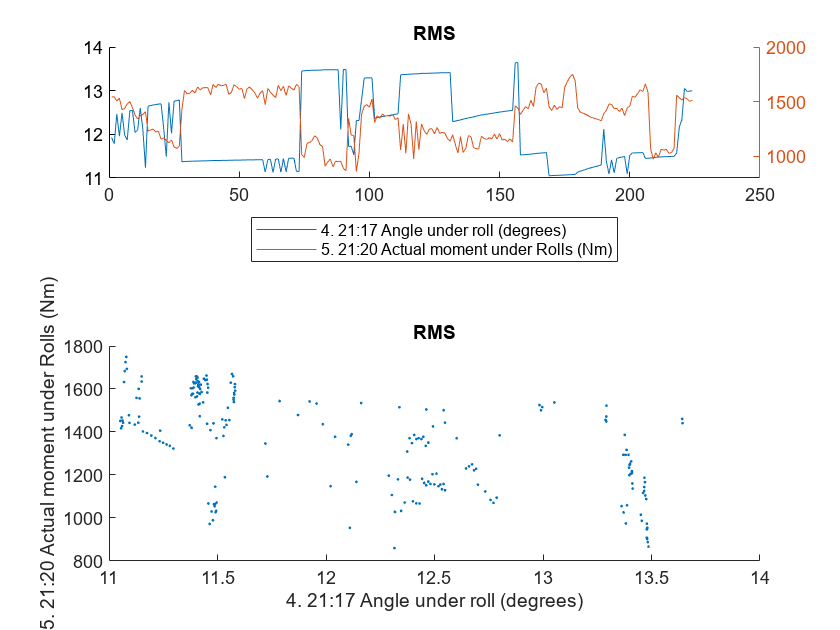

Signal 4:Signal 7 - Features: 1

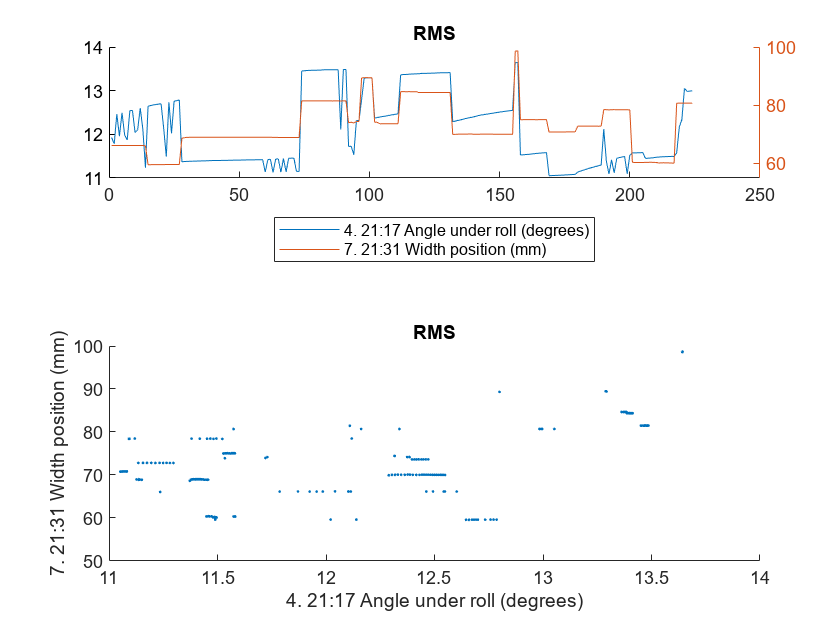

Signal 6:Signal 12 - Features: 1

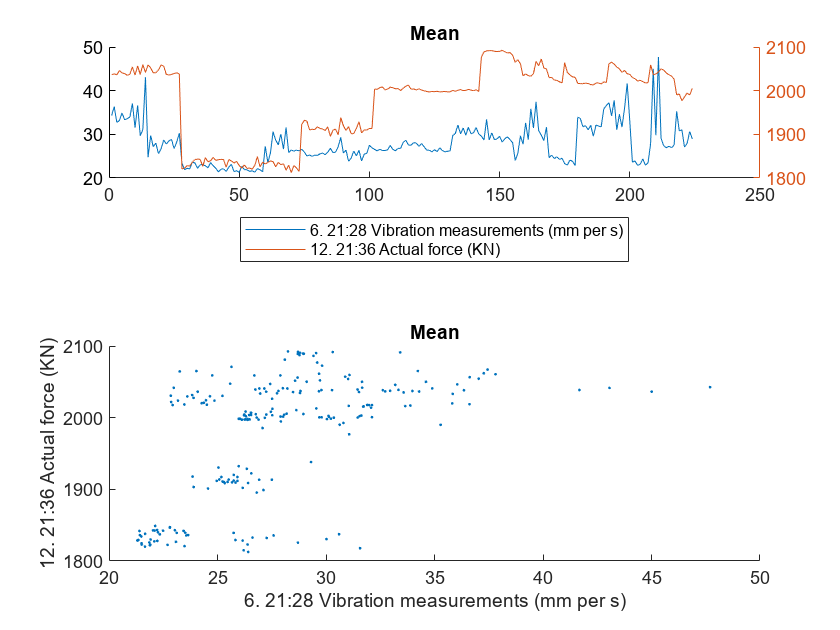

Signal 7:Signal 10 - Features: 1

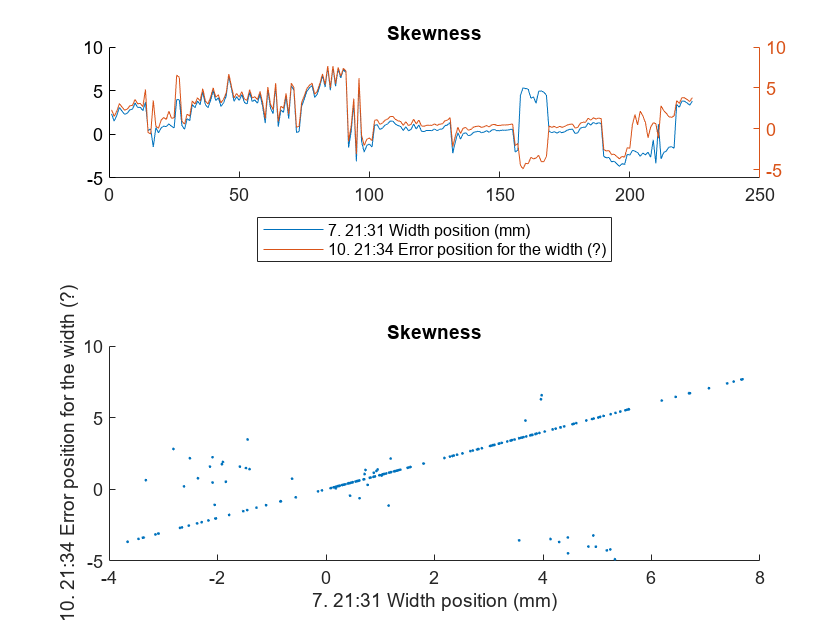

Signal 8:Signal 9 - Features: 1

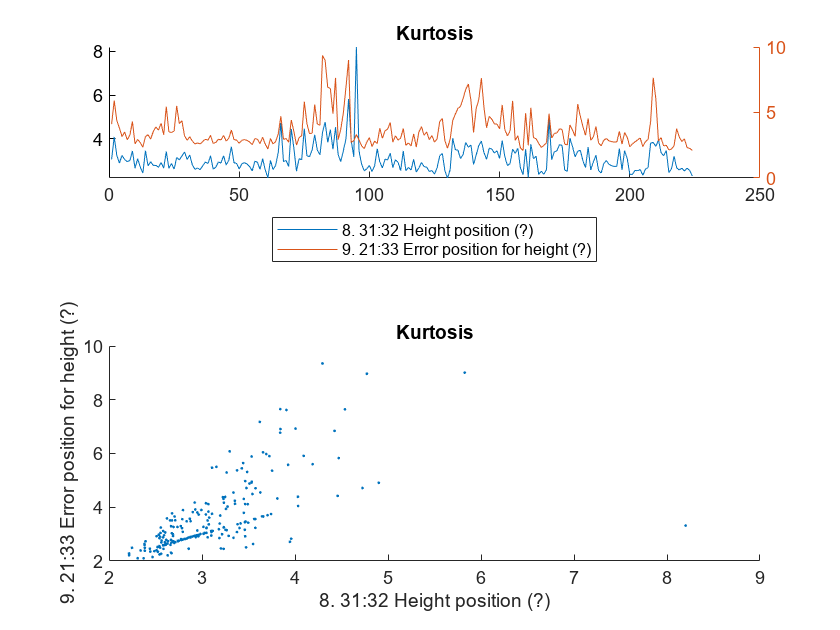

Signal 8:Signal 11 - Features: 1

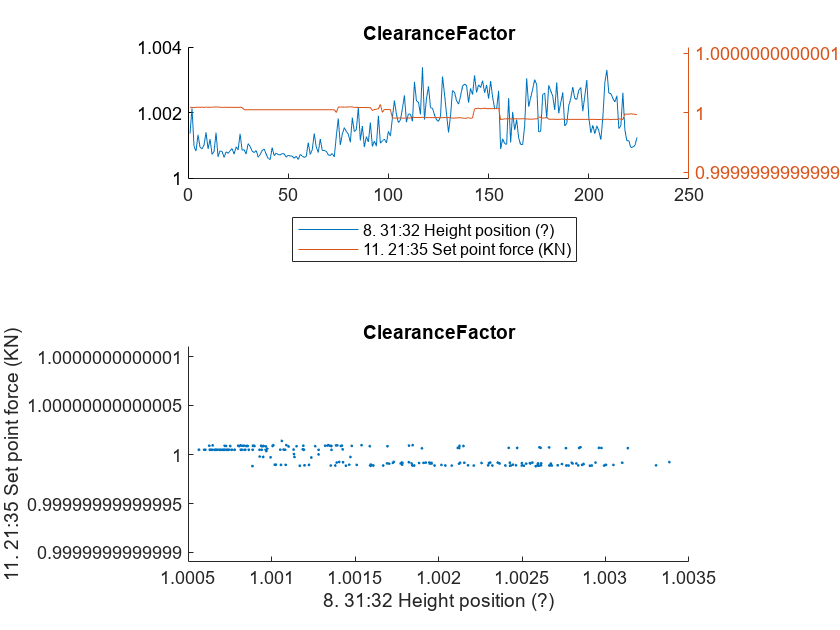

Signal 9:Signal 10 - Features: 3

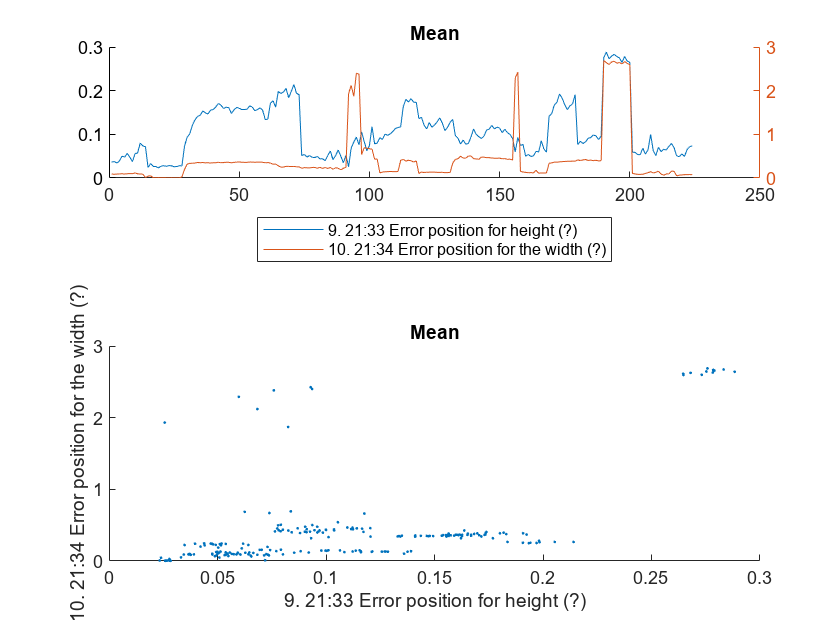

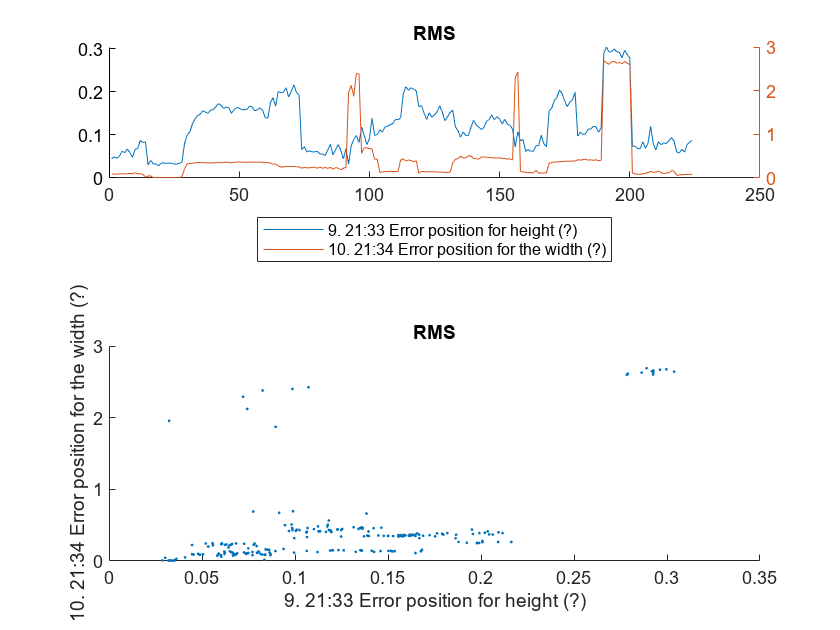

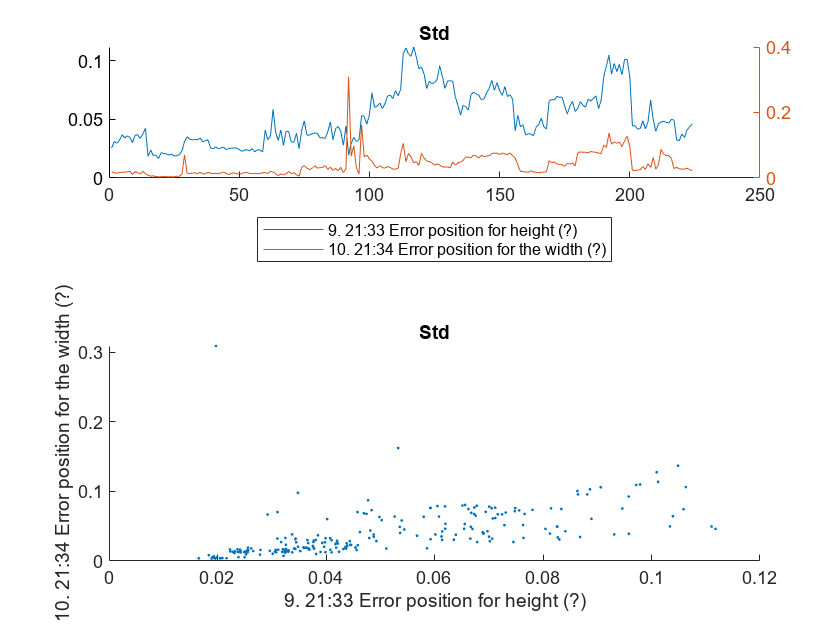

for i=1:numOfSignals
    for j=1:numOfSignals
        if (size(correlatedSignalMatrix{i,j}, 2))
            fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
            plotCorrelatedSignals(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames, signalName, FeaturesAll)
        end
    end
end

## Plot signals vs each other

% for i=1:numOfSignals
%     for j=1:numOfSignals
%         if (size(correlatedSignalMatrix{i,j}, 2))
%             fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
%             plotCorrelatedSignals_XYaxis(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames, signalName, FeaturesAll)
%         end
%     end
% end

## Plot correlated features for same signal

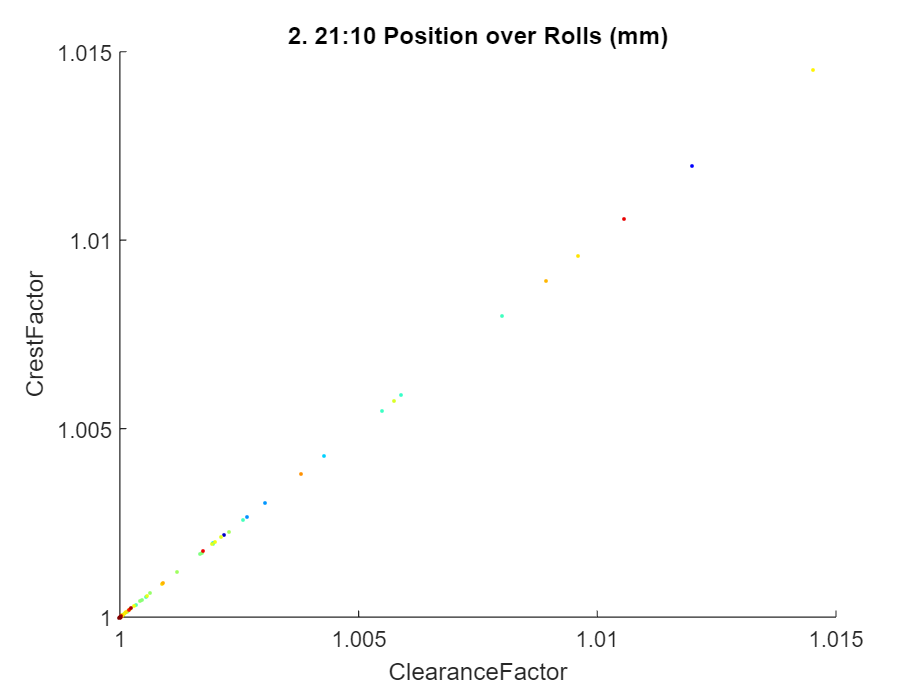

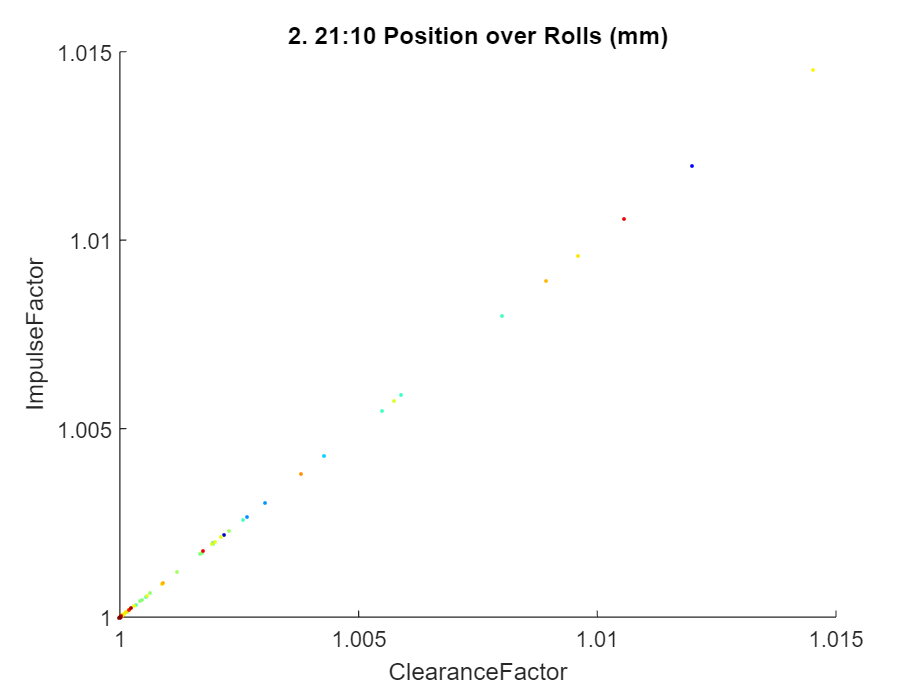

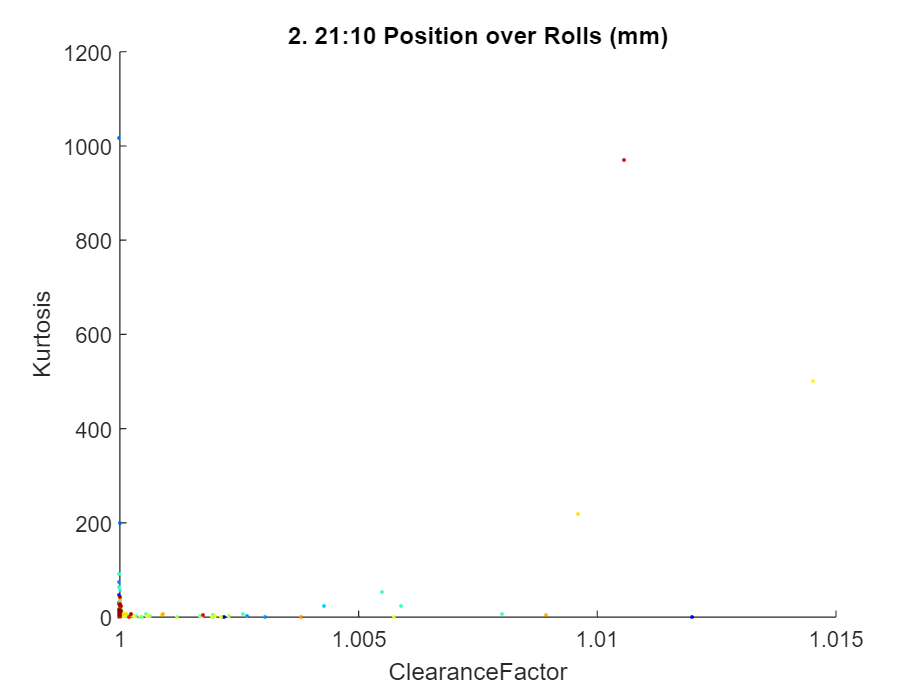

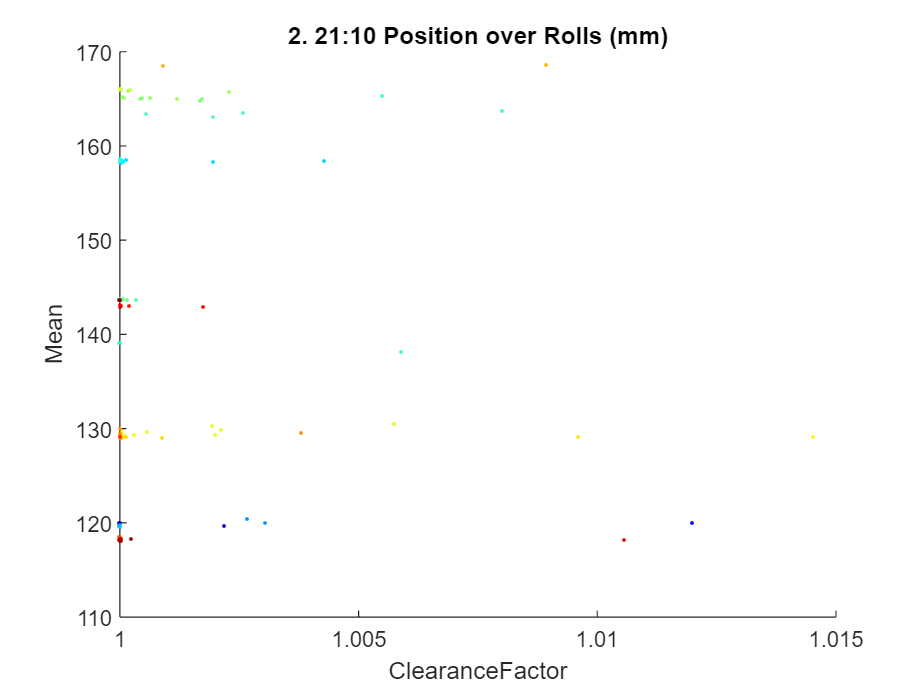

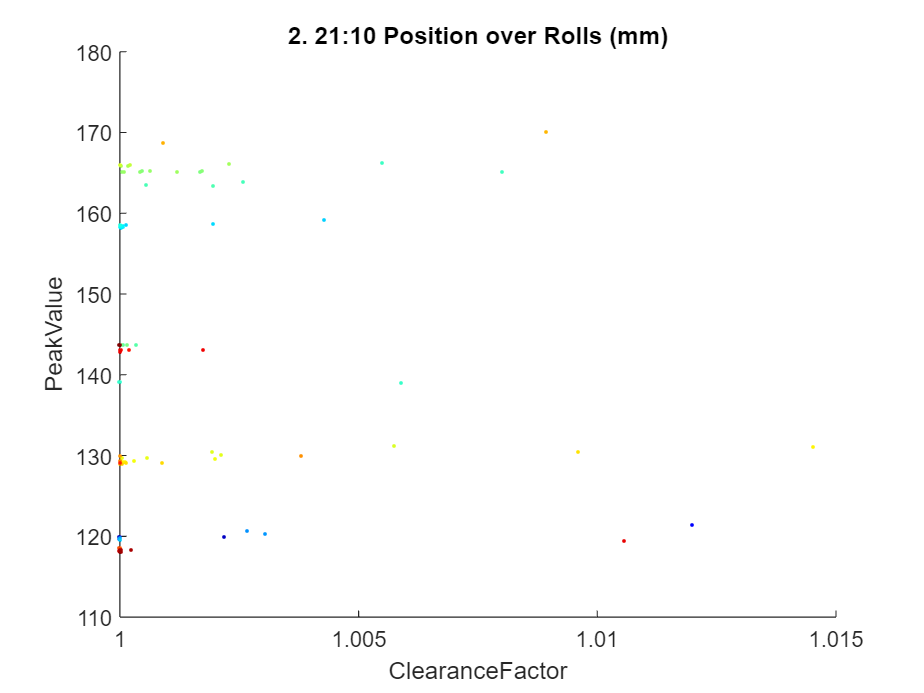

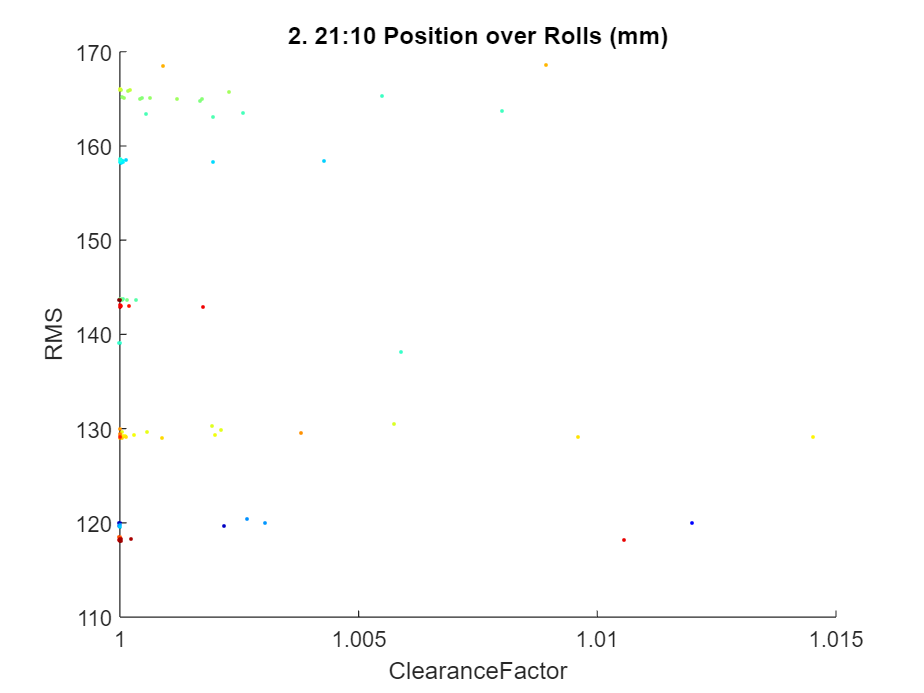

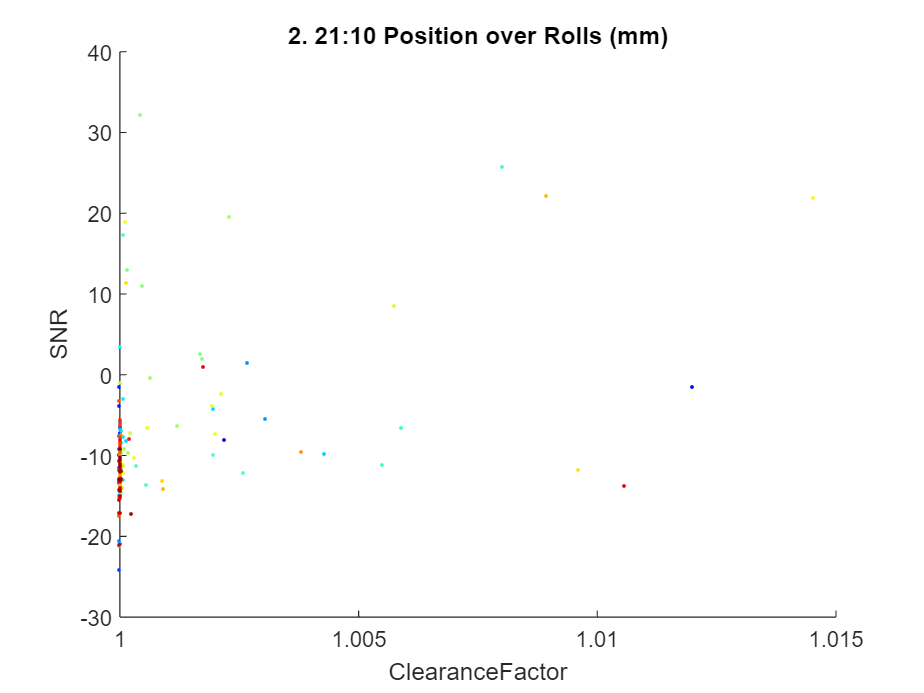

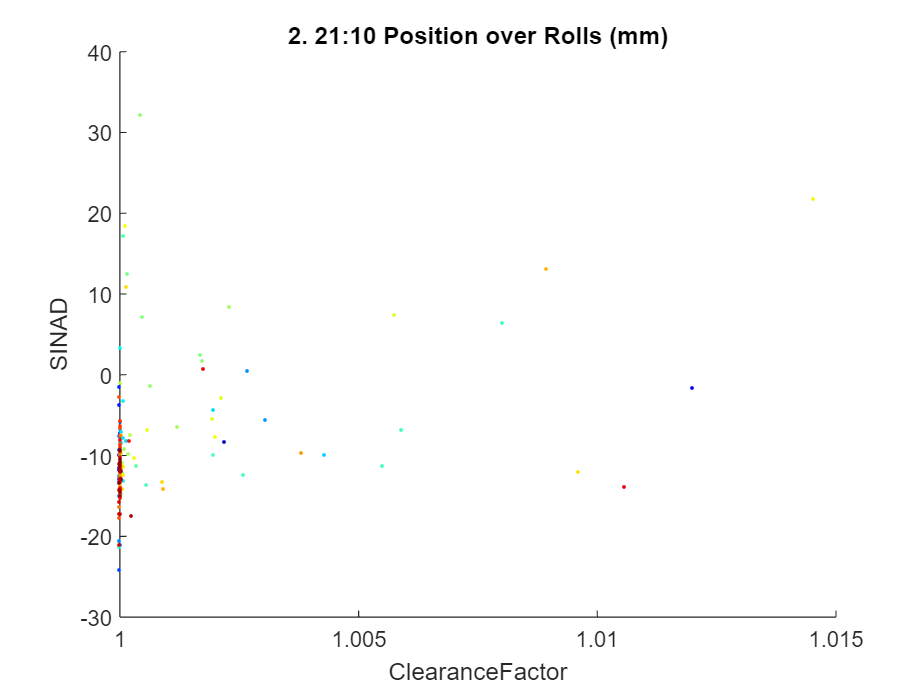

totalPlots = 78

%% Statistical Features: Shape Factor, Skewness, Kurtosis
%% Impulsive Metrics: Peak, Impulse, Crest, Clearance
%% Signal Processing Metrics: SNR, THD, SINAD

signalNum = 2;
%for signalNum = 1 : 12
    plotCorrelatedFeatures(signalNum, sensorNames, featureNames, signalName, FeaturesAll)

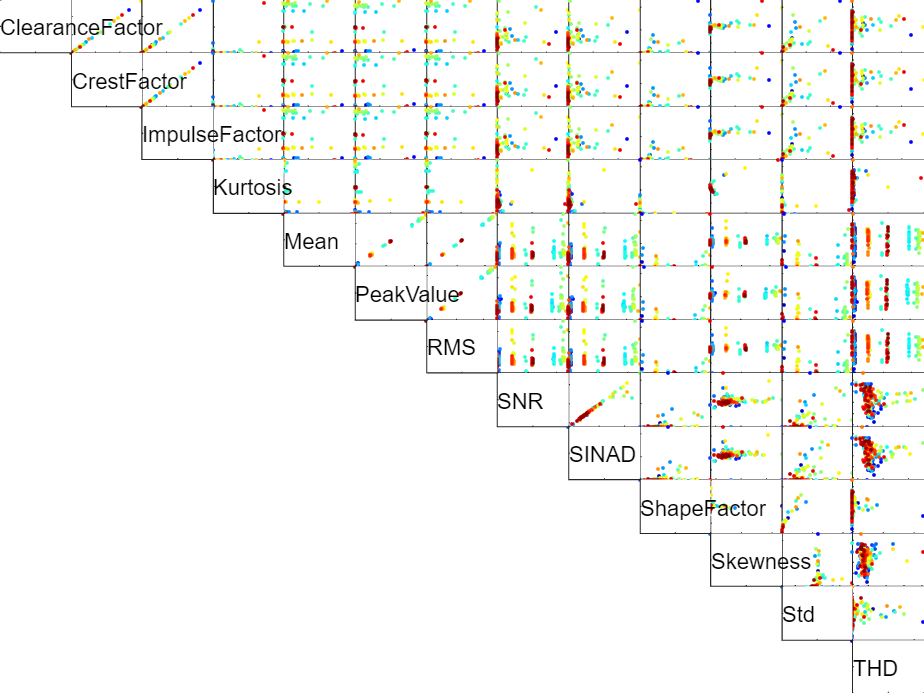

%end

## Function to plot two signals in time domain

function [] = plotCorrelatedSignals(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeaturesAll)
    for i=1:size(correlatedFeatures, 2)
        figure(); 
        subplot(2, 1, 1); hold on;
        feature = featureNames(correlatedFeatures(i));
        plot(FeaturesAll.(signalName(signalNum1) + feature));
        yyaxis right;
        plot(FeaturesAll.(signalName(signalNum2) + feature));
        legend(sensorNames(signalNum1), sensorNames(signalNum2), "Location", 'southoutside');
        title(feature);

        subplot(2, 1, 2); 
        feature = featureNames(correlatedFeatures(i));
        scatter(FeaturesAll.(signalName(signalNum1) + feature), FeaturesAll.(signalName(signalNum2) + feature), 2, 'filled');
        xlabel(sensorNames(signalNum1))
        ylabel(sensorNames(signalNum2));
        title(feature);
    end
end

## Function to plot one signal feature against the same feature of another signal

% function [] = plotCorrelatedSignals_XYaxis(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeaturesAll)
%      for i=1:size(correlatedFeatures, 2)
%         figure();
%         feature = featureNames(correlatedFeatures(i));
%         scatter(FeaturesAll.(signalName(signalNum1) + feature), FeaturesAll.(signalName(signalNum2) + feature), 'filled');
%         xlabel(sensorNames(signalNum1))
%         ylabel(sensorNames(signalNum2));
%         title(feature);
%     end
% end

## Function to plot one feature against a different feature

function [] = plotCorrelatedFeatures(signalNum, sensorNames, featureNames, signalName, FeaturesAll)
    totalPlots = 0;
    numpoints = size(FeaturesAll.(signalName(signalNum) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    for i = 1:size(featureNames, 2)
        feature1 = featureNames(i);
        for j = i+1 : size(featureNames, 2)
            figure();
            feature2 = featureNames(j);
            scatter(FeaturesAll.(signalName(signalNum) + feature1), FeaturesAll.(signalName(signalNum) + feature2), 3, pointidx, 'filled');
            colormap( jet (numpoints) )
            xlabel(feature1);
            ylabel(feature2);
            title(sensorNames(signalNum));
            totalPlots = totalPlots + 1;
        end
    end
    totalPlots
end